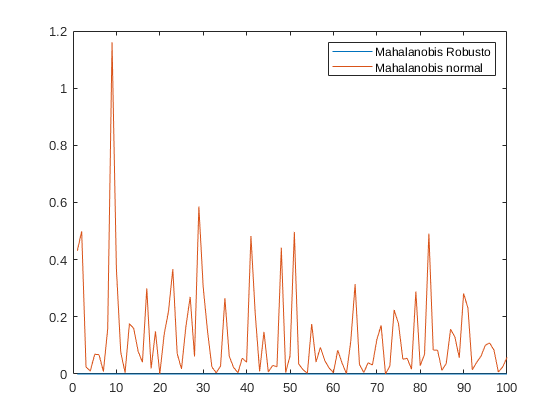

covarianza = hilb(10);
n = 1000;
mu = zeros(10,1);
data =  mvnrnd(mu, covarianza, n);
n = 200;
mu = [0.03,0.04,0.06,0.02,0.01,0.002,0.01,0.005,0.02,0.01];
ruido = mvnrnd(mu,covarianza, n);
dataSucia = cat(1,data,ruido);

X = dataSucia(20,:);
Y = dataSucia(30,:);
[idx,dm,mean,covarianzaRobusta] = kur_main(data);
[idx,dm,mean,covarianzaRobustaSucia] = kur_main(dataSucia);

covarianza = cov(data);
covarianzaSucia = cov(dataSucia);

n = 100;
diferenciasRobustas = zeros(n,1);
diferenciasNormales = zeros(n,1);
for i=1:100
    Y = data(i,:);
   
    distancia = mahalanobis(X',Y',covarianzaRobustaSucia);
    distanciaLimpia = mahalanobis(X', Y', covarianzaRobusta);
    diferenciasRobustas(i) = abs(distancia-distanciaLimpia);
    
    distanciaNormal = mahalanobis(X', Y', covarianzaSucia);
    distanciaNormalLimpia = mahalanobis(X', Y', covarianza);
    diferenciasNormales(i) = abs(distanciaNormalLimpia-distanciaNormal);
end

figure
plot(diferenciasRobustas)
hold on
plot(diferenciasNormales)
legend('Mahalanobis Robusto', 'Mahalanobis normal');

function distancia = mahalanobis(X, Y, covarianza)
    inversa = inv(covarianza);
    distancia = sqrt((X-Y)'*inversa*(X-Y));
end